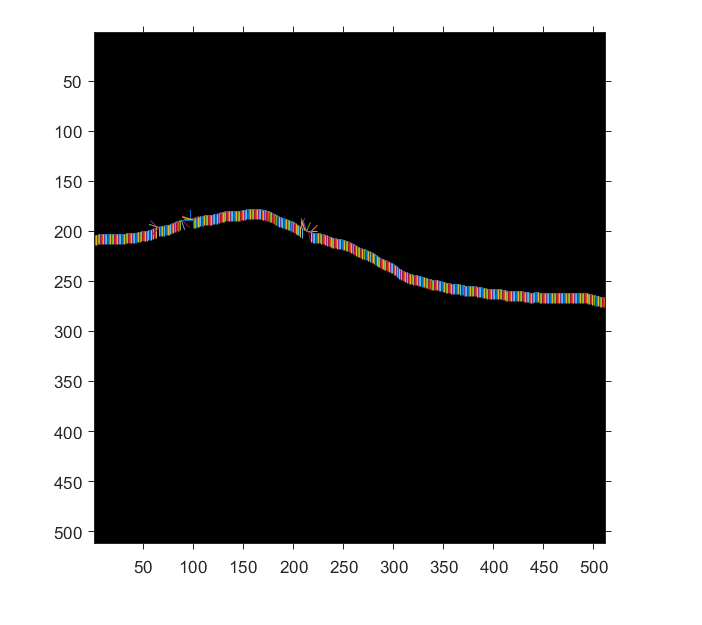


clc

originalImage = imread("fig 1.jpg");
mask = imread("fig 1 target.jpg"); % white represent target region

% Converting original image and mask to grayscale
[row, column, channel] = size(originalImage);
if channel > 1
    I = rgb2gray(originalImage);
else
    I = originalImage;
end

[~,~,channel] = size(mask);
if channel > 1
    mask = rgb2gray(mask);
end

% Finding edges on mask which will 
% return bounded boundary
maskBoundary = edge(mask, 'Canny');

% Finding boundary points of target region
[boundaryY, boundaryX] = find(maskBoundary);

% Binary mask of target(Omega) and source(Phi) region
omega = imbinarize(mask,0.1);
phi = ~omega;

% source region
source = originalImage.*uint8(phi);

% Edges on source image
sourceEdges = edge(I, 'canny').*phi;
% imshow(sourceEdges);
% Magnitude and direction of source image
[sMag, sDir] = imgradient(rgb2gray(source), 'sobel');
[sGx, sGy] = imgradientxy(rgb2gray(source));

% Confidence matrix
% source pixels confidence = 1
% target pixels confidence = 0 (initially)
confidence = double(phi);

texelSize = 9;
texelSize_half = (texelSize-1)/2;
blank = zeros(size(originalImage));

confidence_i = zeros(size(boundaryX));
data_i = zeros(size(boundaryX));
% unitVector normal to target boundary
unitVector_i = zeros(2,1);
for index=2:size(boundaryY,1)-1
    Confidence_val = 0.0;
    Grad_val = 0.0;
    
    % Patch bounds checks
    if boundaryY(index) <= texelSize_half || boundaryX(index) <= texelSize_half
        continue;
    end
    if boundaryY(index)+texelSize_half > size(originalImage,1) || boundaryX(index)+texelSize_half > size(originalImage,2)
        continue;
    end
    %
    %{
    for i=boundaryY(index)-texelSize_half:(boundaryY(index)+texelSize_half)
        for j=boundaryX(index)-texelSize_half:(boundaryX(index)+texelSize_half)
            Confidence_val = Confidence_val + confidence(i,j);
            Grad_val = Grad_val + sMag(i,j);
            for d=1:3
                if blank(i,j,d) == 0
                    % blank(i,j,d)=Source(i,j,d);
                end
            end
        end
    end
    %}
    confidence_i(index) = sum( ...
        confidence(boundaryY(index)-texelSize_half:boundaryY(index)+texelSize_half, ...
        boundaryX(index)-texelSize_half:boundaryX(index)+texelSize_half),'all')/texelSize^2;
    
    i = index;
    px = boundaryX(i); % column
    py = boundaryY(i); % row
    %{
    gradPx = -sin(sDir(py-4,px)*pi/180);
    gradPy = cos(sDir(py-4,px)*pi/180);
    %}
    
    gradPx = -sGy(py,px);
    gradPy = sGx(py,px);
    
    tangent = [boundaryX(i+1)-boundaryX(i-1); boundaryY(i+1)-boundaryY(i-1)];
    vectorMod = sqrt((boundaryX(i+1)-boundaryX(i-1))^2 + (boundaryY(i+1)-boundaryY(i-1))^2);
    
    unitVector_i(1) = -tangent(2)/vectorMod;
    unitVector_i(2) = tangent(1)/vectorMod;
    nPx = unitVector_i(1);
    nPy = unitVector_i(2);
    
    data_i(i) = abs(dot([gradPx,gradPy],[nPx,nPy]))/255;
end

blank = uint8(blank);
imshow(blank);
axis on;
hold on;
plot(boundaryX, boundaryY);
for i=1:size(boundaryY,1)
    px = boundaryX(i);
    py = boundaryY(i);
    p2x = -10*sin(sDir(py-4,px)*pi/180);
    p2y = 10*cos(sDir(py-4,px)*pi/180);
    plot([px,px+p2x],[py,py+p2y]);
end

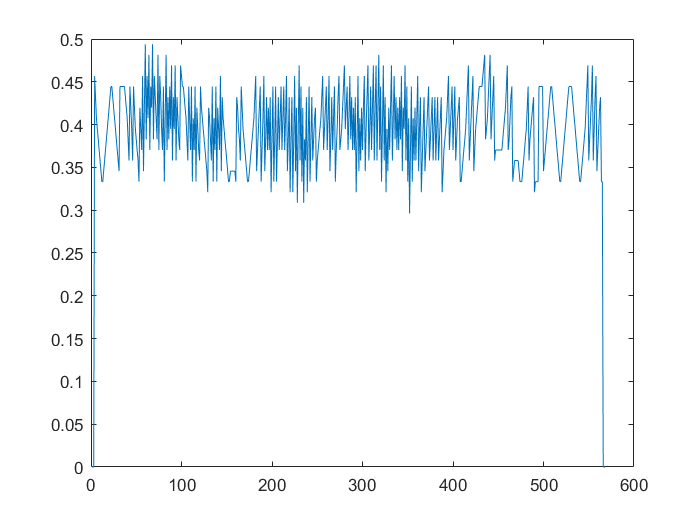

figure;
plot(1:size(boundaryY,1),confidence_i);

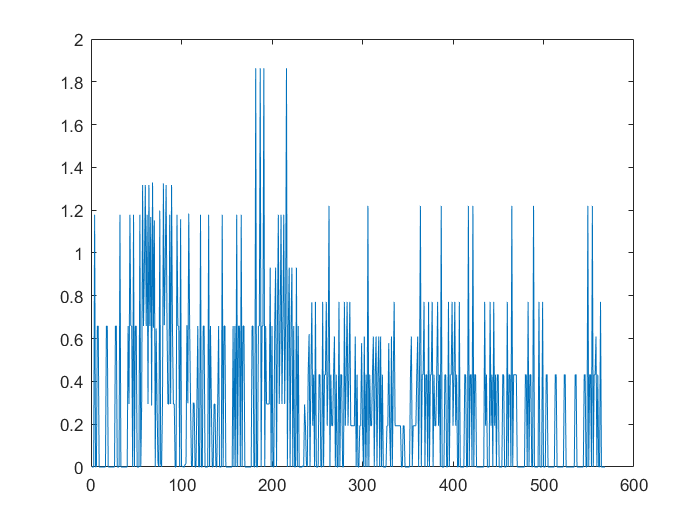

plot(1:size(boundaryY,1),data_i);

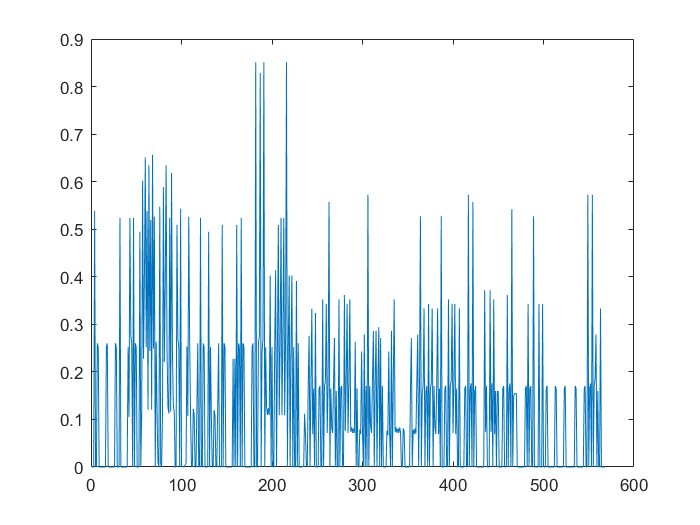

Probability_i = confidence_i.*data_i;
plot(1:size(boundaryY,1), Probability_i);

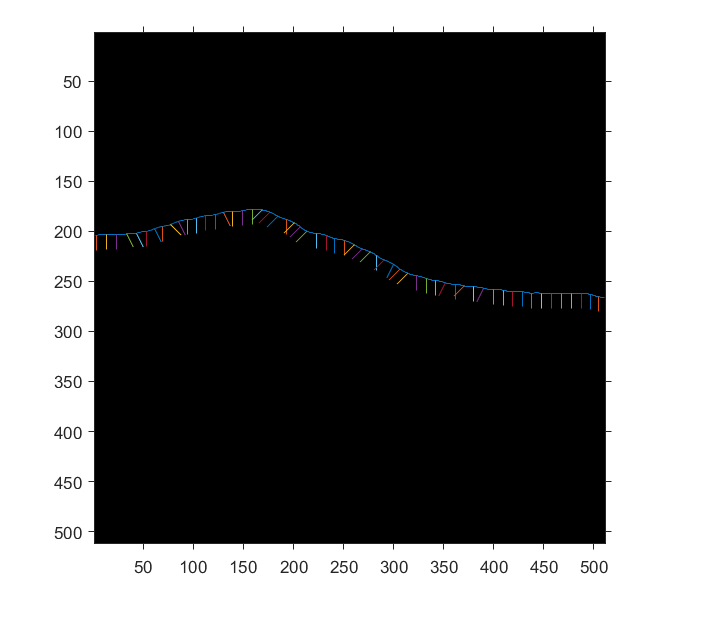

[~,max_Probability_index] = max(Probability_i);

% Unit vector normal to target region boundary
blankImage = uint8(zeros(size(originalImage)));
imshow(blankImage);
hold on;
plot(boundaryX,boundaryY);
% unitVector normal to target boundary
unitVector = zeros(size(boundaryX,1),2);
for i=2:10:size(boundaryY,1)-1
    px = boundaryX(i);
    py = boundaryY(i);
    
    tangent = [boundaryX(i+1)-boundaryX(i-1); boundaryY(i+1)-boundaryY(i-1)];
    vectorMod = sqrt((boundaryX(i+1)-boundaryX(i-1))^2 + (boundaryY(i+1)-boundaryY(i-1))^2);
    unitVector(i,1) = -tangent(2)/vectorMod;
    unitVector(i,2) = tangent(1)/vectorMod;
    p2x = 15*unitVector(i,1);
    p2y = 15*unitVector(i,2);
    
    hold on;
    plot([px,px+p2x],[py,py+p2y]);
end
hold off

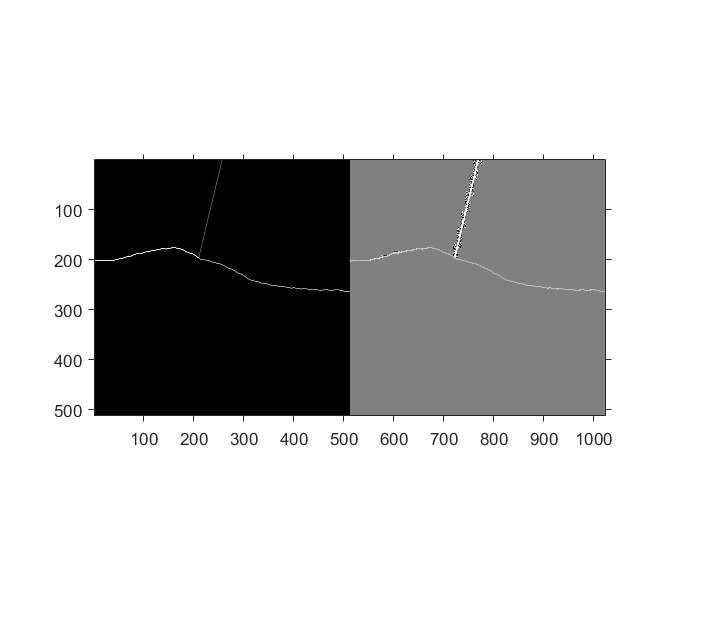


imshowpair(sMag, sDir, 'montage');

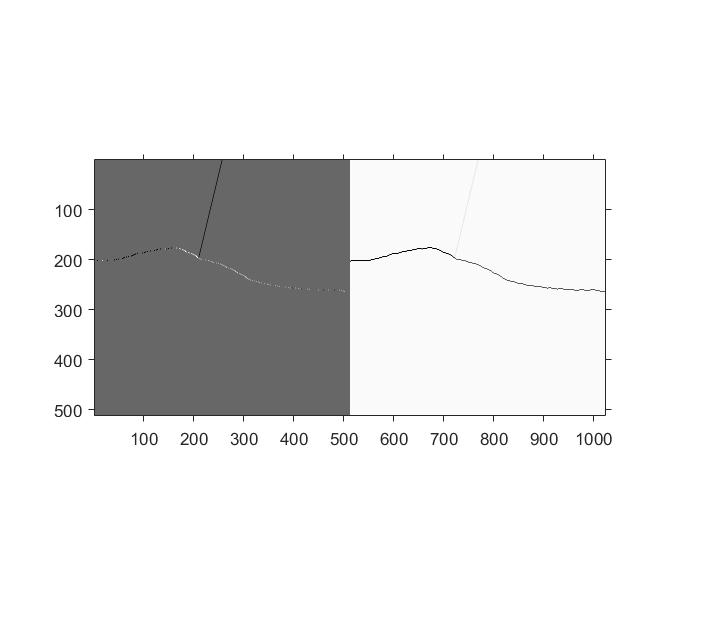

[Gdx,Gdy] = imgradientxy(rgb2gray(source), 'sobel');
imshowpair(Gdx, Gdy, 'montage');

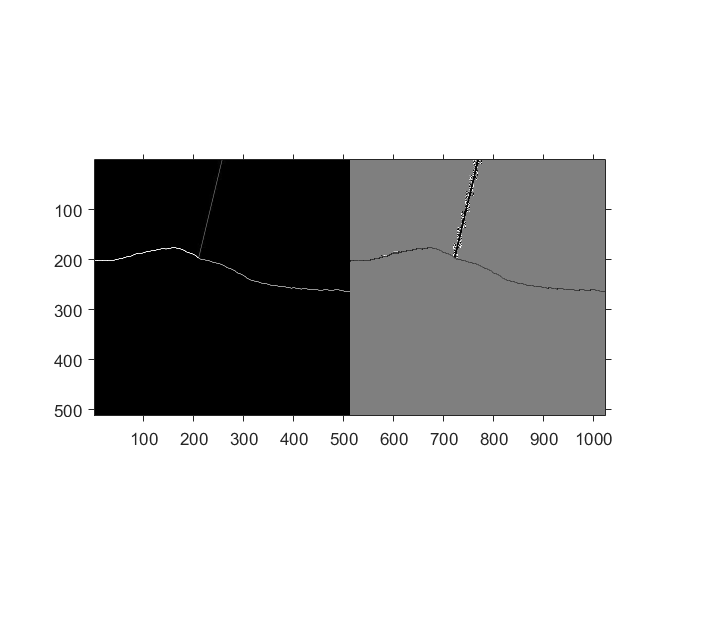

imshowpair(sqrt(Gdx.^2+Gdy.^2), atan2(Gdy,Gdx)*180/pi, 'montage');